clc; clear; close all;

%% ===========================================================
% 1. Load and Preprocess Dataset
% ============================================================
data = readtable('smart_city_energy_dataset.csv');

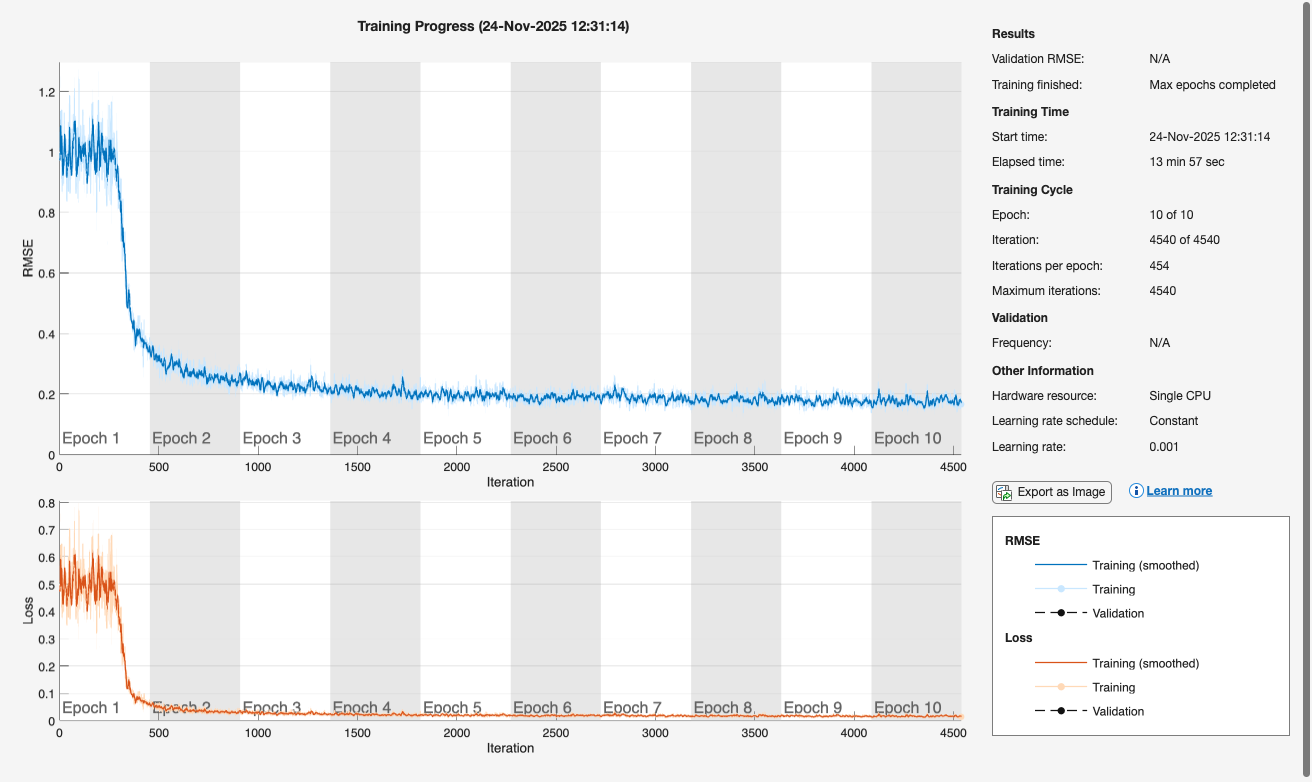

y = data.ElectricityLoad;

%% Optional smoothing
doSmooth = true;
if doSmooth
    [b,a] = butter(4, (1/6)/(0.5));
    y_smooth = filtfilt(b,a,y);
else
    y_smooth = y;
end
data.ElecLoadSmooth = y_smooth;

%% Train/test split index
N = height(data);
trainN = floor(0.8 * N);

%% Detect & fill outliers only in training region
isOut = isoutlier(data.ElecLoadSmooth(1:trainN),'movmedian',24);
trainSeries = data.ElecLoadSmooth(1:trainN);
trainSeriesFilled = filloutliers(trainSeries,'linear',24);

% Apply filled values to dataset
data.ElecLoadFilled = data.ElecLoadSmooth;
data.ElecLoadFilled(1:trainN) = trainSeriesFilled;

%% Cyclic encoding
hour = data.HourOfDay;
dow  = data.DayOfWeek;

data.Hour_sin = sin(2*pi*hour/24);
data.Hour_cos = cos(2*pi*hour/24);
data.DOW_sin  = sin(2*pi*dow/7);
data.DOW_cos  = cos(2*pi*dow/7);

%% Add lag features (HUGE performance boost for LSTMs)
data.LoadLag1   = [NaN; data.ElecLoadFilled(1:end-1)];
data.LoadLag24  = [NaN(24,1); data.ElecLoadFilled(1:end-24)];

%% Remove first 24 rows that contain NaN lag values
data = data(25:end,:);
N = height(data);
trainN = floor(0.8 * N);

%% Select features
features = {'Hour_sin','Hour_cos','DOW_sin','DOW_cos','IsHoliday', 'Temperature__C_','Humidity___','SolarIrradiance_W_m__','CloudCover___', 'WindSpeed_m_s_','LoadLag1','LoadLag24'};

Xdata = data{:,features};
Ydata = data.ElecLoadFilled;

%% Normalize using training split only
Xmu = mean(Xdata(1:trainN,:)); 
Xsigma = std(Xdata(1:trainN,:));
Ymu = mean(Ydata(1:trainN)); 
Ysigma = std(Ydata(1:trainN));

Xnorm = (Xdata - Xmu) ./ Xsigma;
Ynorm = (Ydata - Ymu) ./ Ysigma;

%% ===========================================================
% 2. Build Train/Test Sequences
% ============================================================

seqLen = 168;   % Use 1 week history (improves forecasting dramatically)

XTrain = {}; YTrain = [];
for i = 1:(trainN - seqLen)
    XTrain{end+1} = Xnorm(i:i+seqLen-1,:)';
    YTrain(end+1) = Ynorm(i+seqLen);
end

XTest = {}; YTest = [];
for i = trainN:(N - seqLen)
    XTest{end+1} = Xnorm(i:i+seqLen-1,:)';
    YTest(end+1) = Ynorm(i+seqLen);
end

YTrain = YTrain(:);
YTest  = YTest(:);

%% ===========================================================
% 3. Define LSTM Network
% ============================================================

inputSize = numel(features);

layers = [
    sequenceInputLayer(inputSize)

    lstmLayer(64,'OutputMode','sequence')   % first LSTM
    lstmLayer(32,'OutputMode','last')       % second LSTM

    fullyConnectedLayer(32)
    reluLayer

    fullyConnectedLayer(1)
    regressionLayer
];

%% Training options
options = trainingOptions('adam', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 1e-3, ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.5, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

%% Train network
net = trainNetwork(XTrain, YTrain, layers, options);


%% ===========================================================
% 4. Evaluate Test Performance
% ============================================================

YPredNorm = predict(net, XTest);

% Denormalize    
YPred   = YPredNorm * Ysigma + Ymu;
YActual = YTest     * Ysigma + Ymu;

rmseLSTM = sqrt(mean((YPred - YActual).^2));
R2LSTM = 1 - sum((YPred - YActual).^2) / sum((YActual - mean(YActual)).^2);

fprintf('LSTM RMSE: %.3f kW\n', rmseLSTM);

LSTM RMSE: 24.677 kW


fprintf('LSTM R^2 : %.4f\n', R2LSTM);

LSTM R^2 : 0.9707



%% ===========================================================
% 5. Show Sample Predictions
% ============================================================

numExamples = 10;
fprintf('\nIdx\tActual(kW)\tPredicted(kW)\tError(kW)\n');


Idx	Actual(kW)	Predicted(kW)	Error(kW)


for i = 1:numExamples
    fprintf('%d\t%.2f\t\t%.2f\t\t%.2f\n', ...
        i, YActual(i), YPred(i), YPred(i) - YActual(i));
end

1	709.43		679.39		-30.04
2	663.29		641.15		-22.14
3	604.04		561.27		-42.77
4	551.03		590.82		39.79
5	490.06		500.18		10.11
6	405.77		421.35		15.58
7	313.79		322.80		9.01
8	252.25		269.70		17.45
9	251.68		272.36		20.67
10	315.61		274.18		-41.43


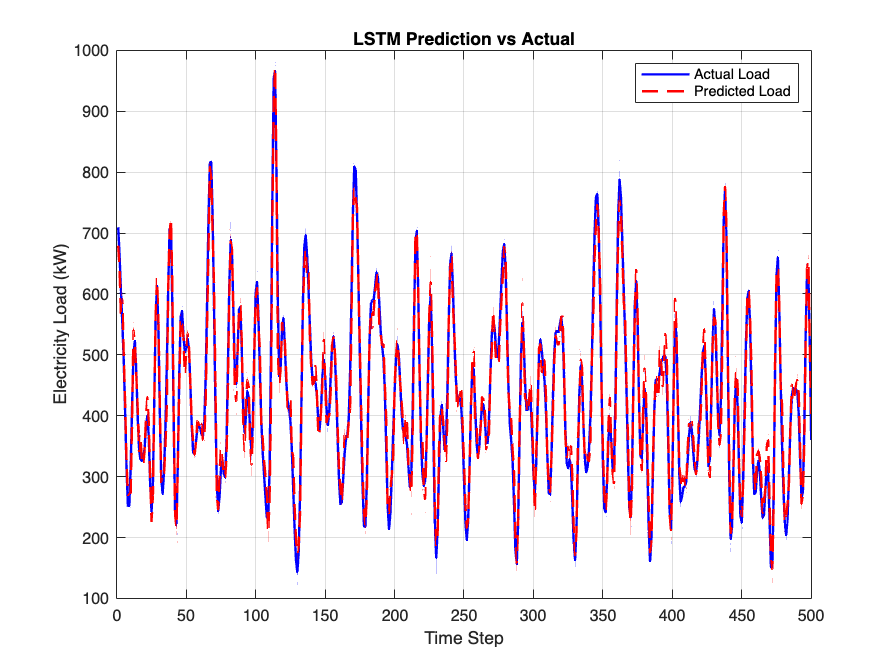


%% ===========================================================
% 6. Plot Comparison
% ============================================================

figure;
plot(YActual(1:500), 'b', 'LineWidth', 1.5); hold on;
plot(YPred(1:500), 'r--', 'LineWidth', 1.5);
legend('Actual Load', 'Predicted Load');
xlabel('Time Step');
ylabel('Electricity Load (kW)');
title('LSTM Prediction vs Actual');
grid on;